syms a(t) phi(t) Y
m1 = 0.1;
m2 = 0.5;
L = 0.1;
g = 9.8;
Da = diff(a,t);
D2a = diff(Da,t);
Dphi = diff(phi,t);
D2phi = diff(Dphi,t);
eqn1 = m1*D2a + m1*g*sin(phi) - m1*a*(Dphi)^2 == 0

$$eqn1(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}a\left(t\right)}{10}-\frac{a\left(t\right)\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{10}+\frac{49\,\sin\left(\varphi \left(t\right)\right)}{50}=0$$

eqn2 = m2*L^2*D2phi + m1*a^2*D2phi + 2*m1*a*Da*Dphi + m1*g*a*cos(phi) + m2*L*g*cos(phi) == 0

$$eqn2(t) = \frac{{a\left(t\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)}{10}+\frac{\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)}{200}+\frac{\frac{\partial }{\partial t}\varphi \left(t\right)\,a\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)}{5}+\frac{49\,\cos\left(\varphi \left(t\right)\right)\,a\left(t\right)}{50}+\frac{49\,\cos\left(\varphi \left(t\right)\right)}{100}=0$$

eqn1s = simplify(lhs(eqn1) - rhs(eqn1), 'Steps', 100)

$$eqn1s(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}a\left(t\right)}{10}-\frac{a\left(t\right)\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{10}+\frac{49\,\sin\left(\varphi \left(t\right)\right)}{50}$$

eqn2s = simplify(lhs(eqn2) - rhs(eqn2), 'Steps', 100)

$$eqn2s(t) = \frac{{a\left(t\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)}{10}+\frac{\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)}{200}+\frac{\frac{\partial }{\partial t}\varphi \left(t\right)\,a\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)}{5}+\frac{49\,\cos\left(\varphi \left(t\right)\right)\,a\left(t\right)}{50}+\frac{49\,\cos\left(\varphi \left(t\right)\right)}{100}$$

[VF,Subs] = odeToVectorField(eqn1s, eqn2s)

$$VF = \left(\begin{array}{c} Y_{2}\\ -\frac{2\,\left(49\,\cos\left(Y_{1}\right)+98\,\cos\left(Y_{1}\right)\,Y_{3}+20\,Y_{2}\,Y_{3}\,Y_{4}\right)}{20\,{Y_{3}}^{2}+1}\\ Y_{4}\\ {Y_{2}}^{2}\,Y_{3}-\frac{49\,\sin\left(Y_{1}\right)}{5} \end{array}\right)$$

$$Subs = \left(\begin{array}{c} \varphi \\ \mathrm{Dphi}\\ a\\ \mathrm{Da} \end{array}\right)$$

odefcn = matlabFunction(VF, 'Vars',{t,Y})

odefcn = function_handle with value:
    @(t,Y)[Y(2);((cos(Y(1)).*4.9e+1+cos(Y(1)).*Y(3).*9.8e+1+Y(2).*Y(3).*Y(4).*2.0e+1).*-2.0)./(Y(3).^2.*2.0e+1+1.0);Y(4);sin(Y(1)).*(-4.9e+1./5.0)+Y(2).^2.*Y(3)]


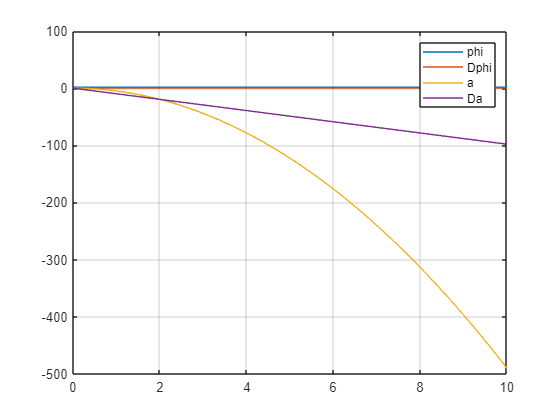

[X,Y] = ode45(odefcn, [0 10], [pi/2 0 0 0]);
figure
plot(X, Y)
grid
legend(string(Subs))